# **Reaction essentiality across multiple models**

**Authors: Miguel A.P. Oliveira, Diana C. El Assal-Jordan, Sylvain Arreckx and Ronan M.T. Fleming, Luxembourg Centre for Systems Biomedicine**

**Reviewers: **

## Introduction

During this tutorial, you will identify and compare which reactions are essential for ATP production within a set of metabolic models. This tutorial is particularly useful when studying metabolic functional abilities across multiple metabolic models.

This driver allows us to perform single reactions to identify essential ones that are required for ATP generation. This means that these essential reactions would carry a zero flux when optimising the ATP consumption reaction (ATPM).

Version 5/12/2017

## EQUIPMENT SETUP

## **Initialize the COBRA Toolbox **and set the solver

Please ensure that The CobraToolbox has been properly installed, and initialized using the `initCobraToolbox` function.

initCobraToolbox



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2017
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done.
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configuring solver enviro

 Done.
 > Setting default solvers ... Done.
 > Saving the MATLAB path ... Done.
   - The MATLAB path was saved as ~/pathdef.m.

 > Summary of available solvers and solver interfaces

			Support 	   LP 	 MILP 	   QP 	 MIQP 	  NLP
	----------------------------------------------------------------------
	cplex_direct 	active        	    0 	    0 	    0 	    0 	    -
	dqqMinos     	active        	    0 	    - 	    - 	    - 	    -
	glpk         	active        	    1 	    1 	    - 	    - 	    -
	gurobi       	active        	    1 	    1 	    1 	    1 	    -
	ibm_cplex    	active        	    0 	    0 	    0 	    - 	    -
	matlab       	active        	    1 	    - 	    - 	    - 	    1
	mosek        	active        	    0 	    0 	    0 	    - 	    -
	pdco         	active        	    1 	    - 	    1 	    - 	    -
	quadMinos    	active        	    0 	    - 	    - 	    - 	    0
	tomlab_cplex 	active        	    0 	    0 	    0 	    0 	    -
	qpng         	passive       	    - 	    - 	    1 	    - 	 

The present tutorial can run with [glpk package](https://opencobra.github.io/cobratoolbox/deprecated/docs/cobra/solvers/changeCobraSolver.html), which does not require additional installation and configuration. Although, for the analysis of large models it is recommended to use the [GUROBI](https://github.com/opencobra/cobratoolbox/blob/master/docs/source/installation/solvers.md) package.

changeCobraSolver('gurobi6','all')


 > Gurobi interface added to MATLAB path.
 > gurobi (version 751) is compatible and fully tested with MATLAB R2016b on your operating system.
 > Solver for LP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > gurobi (version 751) is compatible and fully tested with MATLAB R2016b on your operating system.
 > Solver for MILP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > gurobi (version 751) is compatible and fully tested with MATLAB R2016b on your operating system.
 > Solver for QP problems has been set to gurobi.

 > Gurobi interface added to MATLAB path.
 > gurobi (version 751) is compatible and fully tested with MATLAB R2016b on your operating system.
 > Solver for MIQP problems has been set to gurobi.
 > Solver gurobi not supported for problems of type NLP. Currently used: matlab 


## Define models directory

In this tutorial, we provide the metabolic models of four gut microbiotas. All models were extracted from the latest version of the database of the human cellular metabolism, Recon 3D [3]. For extra information about metabolites structures and reactions, and to download the latest COBRA model releases, visit the Virtual Metabolic Human database (VMH, [https://vmh.life](https://vmh.life)). 

modelsFileName = {'Acidaminococcus_fermentans_DSM_20731.mat','Acidaminococcus_intestini_RyC_MR95.mat','Abiotrophia_defectiva_ATCC_49176.mat','Acinetobacter_calcoaceticus_PHEA_2.mat'};

modelsFileName =     'Acidaminococcus_fermentans_DSM_20731.mat'    'Acidaminococcus_intestini_RyC_MR95.mat'    'Abiotrophia_defectiva_ATCC_49176.mat'    'Acinetobacter_calcoaceticus_PHEA_2.mat'


Before proceeding with the simulations, locate the directory with all models: 

modelsDir = getDistributedModelFolder(modelsFileName{1}); % all tutorial models are in the same directory

## PROCEDURE 

## **1. Define objective function and solver to use:**

% Objective function to be used:
objFun = 'ATPS4';

## 2. Study essential reactions across all models based on a specific condition:

Perform single reaction deletion (`singleRxnDeletion.m`) across all models by using the function `essentialRxn4MultipleModels.m` 

TIMING: aprox. 20 seconds

% modelsDir = '/hdd/work/sbgCloud/programReconstruction/projects/brainMetabolism/results/modelGeneration/models/cutoff_50'

[ essentialRxn4Models, essential] = essentialRxn4MultipleModels(modelsFileName, modelsDir, objFun);

 
Analysing model: 
Acidaminococcus_fermentans_DSM_20731.mat
Single reaction deletion analysis in progress ...

Define a essentiality threshold that represent the max flux through 'ATPS4mi' that would still represent insignificant ATP production.

essentialityThreshold = 30;

Study reaction essentiality across all models by conditional search.

**2.1. Identify reactions that are essential in at least one model:**

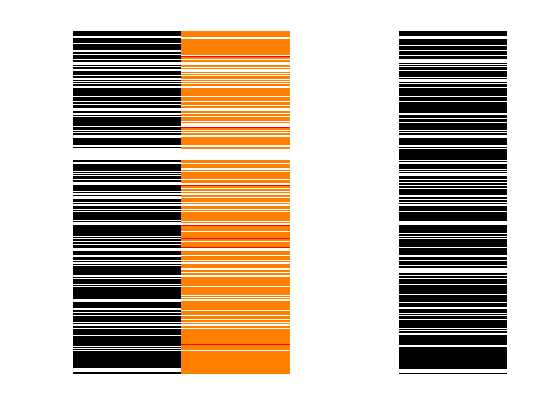

numModelsPresent = 1;
essentialInterest = plotEssentialRxns( essential, essentialRxn4Models, essentialityThreshold, numModelsPresent);

**2.2. Identify reactions that are essential and present in all models:**

numModelsPresent = size(essentialRxn4Models,2);
essentialInterest = plotEssentialRxns( essential, essentialityThreshold, numModelsPresent)

**2.3. Identify reactions that are never essential in all models:**

numModelsPresent = 1;
essentialInterest = plotEssentialRxns( essential, essentialityThreshold, numModelsPresent)
